%%% READ ME %%%
% Scriptet virker kun på Matlab 2020 og nyere
% Legg ActualSpeedrun mappen i C:\Users\Username\Documents\MATLAB
% VIEW -> HIDE CODE (for beste visning

addpath('ActualSpeedrun/Funksjoner/') % Legger til folder med funksjoner til matlab path
addpath('ActualSpeedrun/Images') % Legger til folder med bilder i matlab path


clearvars %clear all variables
%clear all % clear all, men forsinker koden om den kjøres hver gang

# LaPlace

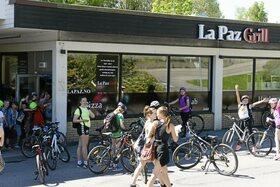

*Laplace Grill, Kolbotn*

**Fra f(t) til F(S)**

syms f(t) a b t s u
f(t) = t*sin(5*t)

$$f(t) = t\,\sin\left(5\,t\right)$$

F(s) = laplace(f);1

ans = 1

Fsimpl = simplify(F);
if F == Fsimpl
    display(F)
else
    display(F), display(Fsimpl)
end

$$F(s) = \frac{10\,s}{{\left(s^{2}+25\right)}^{2}}$$

**First Shift**

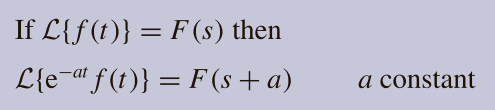

syms a t
a = 3;
firstShift = F(s+a);
firstShiftSimplified = simplify(firstShift);

if firstShift == firstShiftSimplified
    display(firstShift)
else
    display(firstShift),display(firstShiftSimplified)
end

$$firstShift = \frac{10\,\left(s+3\right)}{{\left({\left(s+3\right)}^{2}+25\right)}^{2}}$$

firstShiftExpForm = exp(-(a*t))*f(t)

$$firstShiftExpForm = t\,\sin\left(5\,t\right)\,{\mathrm{e}}^{-3\,t}$$

**Second Shift Theorem**

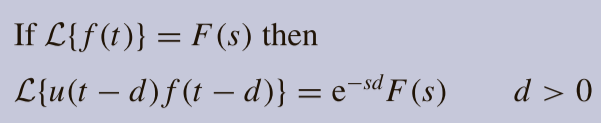

syms d
d = 1

d = 1

% secondShift=F()

 

**Invers Laplace**

(Får det ikke tilbake til samme form desverre)

syms f(t) a b t s S
F(S) = (2*s-7)/(s^2+5*s+4)

$$F(S) = \frac{2\,s-7}{s^{2}+5\,s+4}$$


f(s) = ilaplace(F)

$$f(s) = 5\,{\mathrm{e}}^{-4\,t}-3\,{\mathrm{e}}^{-t}$$

fSimpl = simplify(f)    

$$fSimpl(s) = 5\,{\mathrm{e}}^{-4\,t}-3\,{\mathrm{e}}^{-t}$$

$$ODE(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)+2\,\frac{\partial }{\partial t}x\left(t\right)+x\left(t\right)={\mathrm{e}}^{-t}$$